[m,na]=size(Figure2DataS1);
maxAmp=max(Figure2DataS1(3:11,2));
minAmp=min(Figure2DataS1(3:11,2));
Magnitude=maxAmp-minAmp;
AvgBaselineResp=mean(Figure2DataS1(m-10:m,2))

AvgBaselineResp = 0.1727

hold on
plot(Figure2DataS1(:,1), Figure2DataS1(:,2));
xlabel("Time (ms)");
ylabel("Magnitude (uV)");plot(Figure2DataS1(:,1), Figure2DataS1(:,2));
ABRShade=[2 10];
BaselineShade= [m-10 m-1]

BaselineShade =     21    30


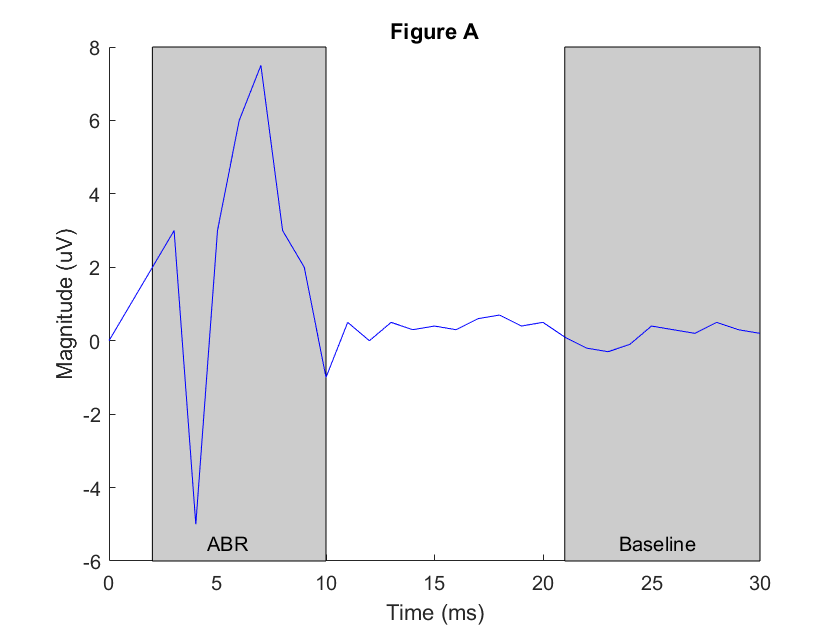

patch([ABRShade(1) ABRShade(1), ABRShade(2) ABRShade(2)], [min(ylim) max(ylim) max(ylim) min(ylim)], [0.8 0.8 0.8])
patch([BaselineShade(1) BaselineShade(1), BaselineShade(2) BaselineShade(2)], [min(ylim) max(ylim) max(ylim) min(ylim)], [0.8 0.8 0.8])
plot(Figure2DataS1(:,1), Figure2DataS1(:,2),"Color",'b');
text(4.5,minAmp-0.5,'ABR');
text(m-7.5, minAmp-0.5, 'Baseline');
title("Figure A");
hold off